clear;
load("Violine_example.mat");
sound(0.2 * example, Fs_example);
pause(2);

f = Fs_example*(0:(length(example)/2))/length(example);
X = fft(example);

Xn = abs(X/length(example));
Xn_2 = Xn(1:length(example)/2+1); 

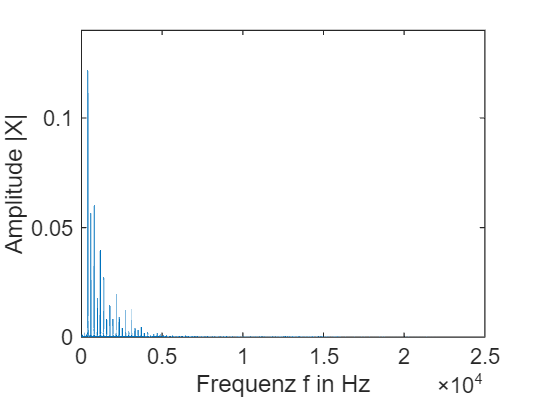

Xn_2(1:end) = 2 * Xn_2(1:end);

plot(f, Xn_2);
xlabel("Frequenz f in Hz");
ylabel("Amplitude |X|");


global Fs lengthOf1 m c_m fa1;
Fs = 44100; % Samplerate
lengthOf1 = 0.8; % Dauer einer "ganzen Note" in Sekunden
m = [1 2 3 4 6 8 10 12 14 16 18 20 24]; % Vektor der implementierten Obertöne
fa1 = 390; % Grundton abgelesen (höchste Amplitude) 
c_m = [0.122 0.06 0.039 0.008 0.009 0.013 0.001 0.002 0 0 0 0 0]; % abgelesen (13 höchste Amplituden)
mainVolume = 0.1;

tone(mainVolume);

Die Nachbildung klingt nicht realistisch wie eine Violine. Man kann eine gewisse Ähnlichkeit zu dem Sample erkennen. Dieses deckt jedoch nicht komplett alle möglichen Töne auf dem Instrument ab. Zudem erkennt man sehr stark die Übergänge zwischen den Tönen, ähnlich zu einem Klavier.

Idee: mehr Amplituden betrachten

m =   [0.006 0.052 1 1.501 2 2.502 3 3.503 4 4.505 5.004 5.506 6 6.507 7.007 7.508 8 8.509 9.009 9.511 10 10.512 11.012 11.511 12];
c_m = [0.001 0.002 0.122 0.056 0.06 0.018 0.039 0.027 0.008 0.014 0.008 0.019 0.009 0.004 0.012 0.002 0.013 0.004 0.003 0.004 0.002 0.002 0.001 0.001 0.002];
tone(mainVolume);
